## **Gradient Optimization (GrOpt) Demo**

% PART 1: Monopolar gradient shape (triangle vs. trapezoid) depends on M0 and gradient hardware
clear params;
params.mode = 'free';
params.gmax = 0.05;     % Maximum gradient amplitude, T/m
params.smax = 100;      % Maximum slew rate, T/m/s
M0 = 50;                % Gradient zeroth moment, T/m x s
params.dt = 10e-6;      % Gradient raster time, s

% Initialize the moment parameters
params.moment_params = [];  
params.moment_params(:,end+1) = [0, 0, 0, -1, -1, M0, 1.0e-3];
% [axis dir, moment order, reference time, start time, end time, desired moment, tolerance]

[G, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 1.875 1.563 1.406 1.484 1.523 1.504 1.514 1.519 1.516 Final TE = 1.516 ms


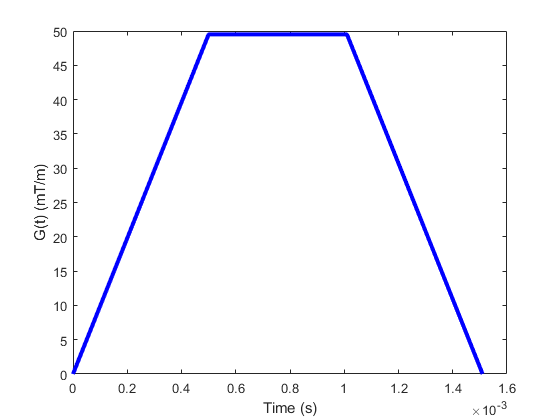

t = 0:params.dt:(numel(G)-1)*params.dt;   % Time vector (ms)
figure; plot(t,G.*1000,'b','Linewidth',3);
  ylabel('G(t) (mT/m)');
  xlabel('Time (s)');

% PART 2: Bipolar gradients
clear params;
params.mode = 'free';
params.gmax = 0.05;     % Maximum gradient amplitude, T/m
params.smax = 100;      % Maximum slew rate, T/m/s
M0 = 0;                 % Gradient zeroth moment, T/m x s
M1 = 11.74;             % Gradient first moment, T/m x s^2
params.dt = 10e-6;      % Gradient raster time, s

% Initialize the moment parameters
params.moment_params = [];  
params.moment_params(:,end+1) = [0, 0, 0, -1, -1, M0, 1.0e-3];
params.moment_params(:,end+1) = [0, 1, 0, -1, -1, M1, 1.0e-3];
% [axis dir, moment order, reference time, start time, end time, desired moment, tolerance]

[G, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 1.875 1.563 1.719 1.641 1.602 1.582 1.572 1.567 1.565 Final TE = 1.567 ms


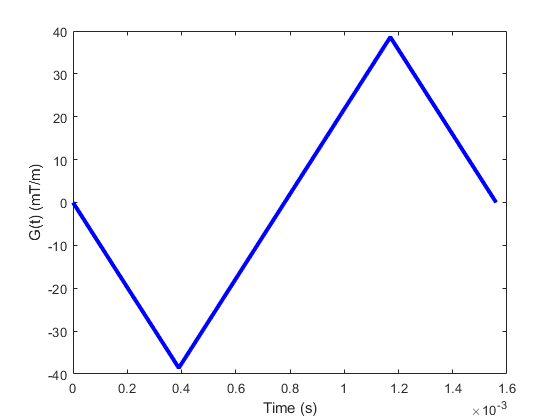

t = 0:params.dt:(numel(G)-1)*params.dt;   % Time vector (ms)
figure; plot(t,G.*1000,'b','Linewidth',3);
  ylabel('G(t) (mT/m)');
  xlabel('Time (s)');

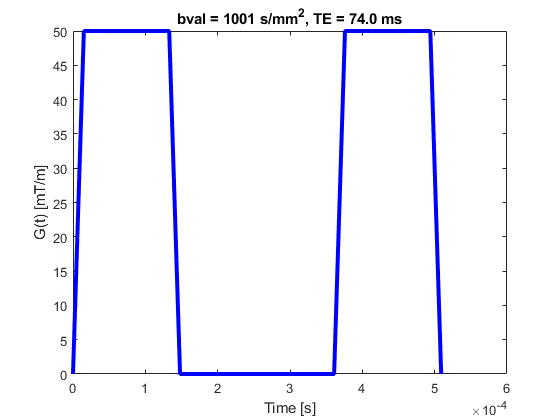

% PART 3A: Conventional Monopolar Diffusion Gradients
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 100;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms

[TE,G,b] = design_symmetric_gradients(params.b,params.T_readout,params.T_90,params.gmax,params.MMT);

t = (0:1:(length(G)-1)).*1e-6;
figure; plot(t,G*1000,'b','Linewidth',3); hold on;
        xlabel('Time [s]'); ylabel('G(t) [mT/m]'); 
        title(['bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])

% PART 3B: Convex Optimized Diffusion Encoding (CODE) Gradients
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 100;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
params.dt_out = 10e-6;      % Interpolated gradient raster time, s
tmin = 50;                  % Minimum time search, ms
tmax = 100;                 % Maximum time search, ms

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (13 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13  Done  TE = 69.160000


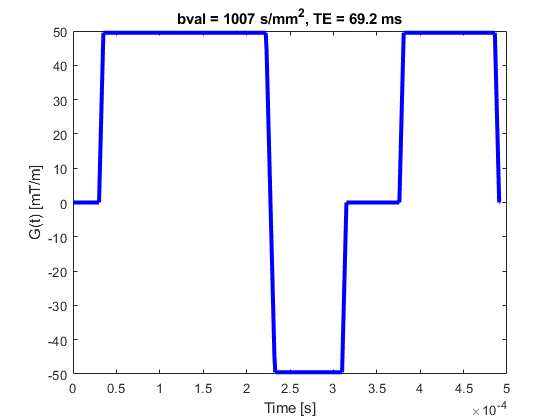

if isfield(params,'dt_out')
    params.dt = params.dt_out;
end

b = get_bval(G, params);
TE = length(G)*params.dt*1e3 +  params.T_readout;

t = (0:params.dt:(length(G)-1)*params.dt)./100;
figure; plot(t,G*1000,'b','Linewidth',3); hold on;
        xlabel('Time [s]'); ylabel('G(t) [mT/m]'); 
        title(['bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])

% PART 3C: Eddy current Nulled-Convex Optimized Diffusion Encoding (EN-CODE) Gradients
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 100;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
params.dt_out = 10e-6;      % Interpolated gradient raster time, s
tmin = 50;                  % Minimum time search, ms
tmax = 100;                 % Maximum time search, ms

% Eddy current compensation [time constant (ms), target, tolerance, mode]
params.eddy_params = [];    
params.eddy_params(:,end+1) = [30, 0, 1.0e-4, 0];

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (13 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13  Done  TE = 90.610000


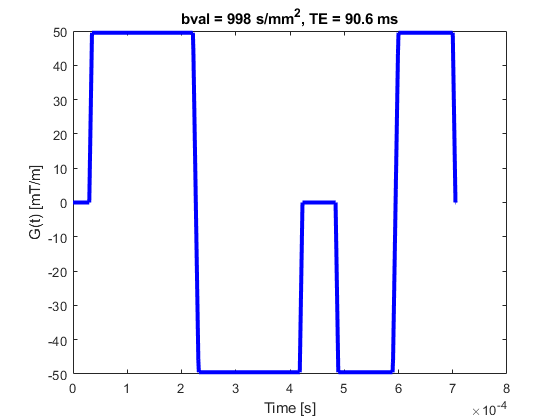

if isfield(params,'dt_out')
    params.dt = params.dt_out;
end

b = get_bval(G, params);
TE = length(G)*params.dt*1e3 +  params.T_readout;

t = (0:params.dt:(length(G)-1)*params.dt)./100;
figure; plot(t,G*1000,'b','Linewidth',3); hold on;
        xlabel('Time [s]'); ylabel('G(t) [mT/m]'); 
        title(['bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])

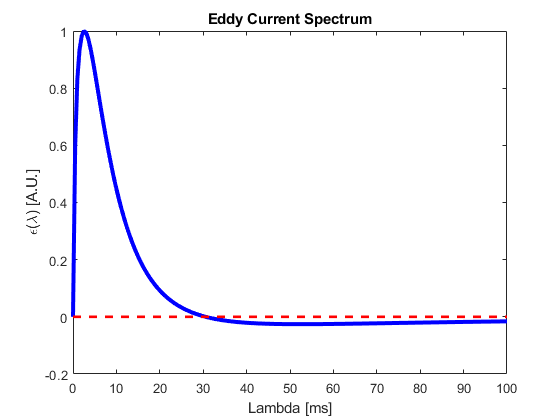

        
% Plot Eddy Current Spectra
lam_max = 100; % maximum lambda [ms] for eddy spectrum analysis
[all_lam, all_e] = get_eddy(lam_max, G, params.dt);
figure; plot(all_lam, all_e./max(all_e(:)),'b','Linewidth',3); hold on;
        xlabel('Lambda [ms]'); ylabel('\epsilon(\lambda) [A.U.]'); 
        title(['bval = ' num2str(b,'%.0f') ' s/mm^{2}' ', TE = ' num2str(TE,'%.1f') ' ms'])
        hline = refline([0 0]); hline.Color = 'r'; hline.LineStyle = '--'; hline.LineWidth = 2;
        title('Eddy Current Spectrum');        

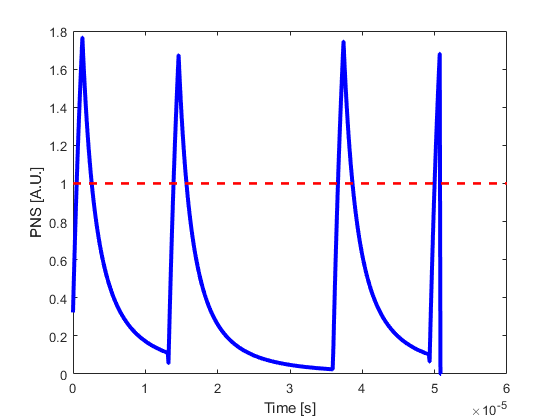

% PART 4A: Peripheral Nerve Stimulation (PNS) - Monopolar gradients at 200T/m/s
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 200;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
params.dt_out = 10e-6;      % Interpolated gradient raster time, s

[~,G,~] = design_symmetric_gradients(params.b,params.T_readout,params.T_90,params.gmax,params.MMT);
        
if isfield(params,'dt_out')
    params.dt = params.dt_out;
end

t = (0:params.dt:(length(G)-1)*params.dt)./100;
y = abs(get_stim(G, params.dt)');
figure; plot(t,y,'b','Linewidth',3);
    xlabel('Time [s]'); ylabel('PNS [A.U.]');
    hline = refline([0 1.0]); hline.Color = 'r'; hline.LineStyle = '--'; hline.LineWidth = 2;

% PART 4B Peripheral Nerve Stimulation (PNS) - CODE gradients at 200T/m/s
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 200;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
params.dt_out = 10e-6;      % Interpolated gradient raster time, s
tmin = 50;                  % Minimum time search, ms
tmax = 100;                 % Maximum time search, ms

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (13 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13  Done  TE = 68.660000


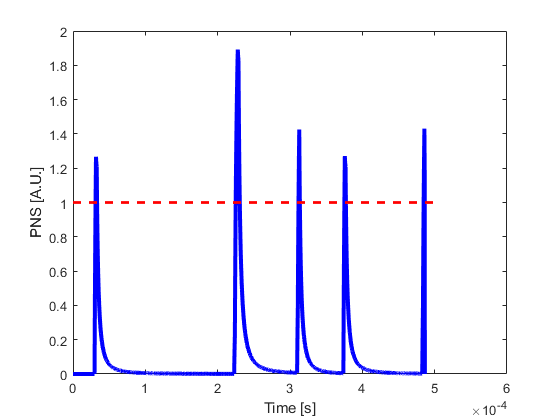


if isfield(params,'dt_out')
    params.dt = params.dt_out;
end

t = (0:params.dt:(length(G)-1)*params.dt)./100;
y = abs(get_stim(G, params.dt)');
figure; plot(t,y,'b','Linewidth',3);
    xlabel('Time [s]'); ylabel('PNS [A.U.]');
    hline = refline([0 1.0]); hline.Color = 'r'; hline.LineStyle = '--'; hline.LineWidth = 2;

% PART 4C Peripheral Nerve Stimulation (PNS) - CODE gradients with PNS constraint
clear params;
params.mode = 'diff_bval';
params.gmax = 0.05;         % Maximum gradient amplitude, T/m
params.smax = 200;          % Maximum slew rate, T/m/s
params.MMT = 0;             % Desired moment nulling (M0 = 0 for Monoopolar)
params.b = 1000;            % Diffusion b-value, s/mm^2
params.T_readout = 20;      % Time from start to center of EPI readout, ms
params.T_90 = 3;            % Duration of excitation pulse, ms
params.T_180 = 6;           % Duration of refocusing pulse, ms
params.dt = 100e-6;         % Gradient raster time for optimization, s
% params.dt_out = 10e-6;      % Interpolated gradient raster time, s
tmin = 50;                  % Minimum time search, ms
tmax = 100;                 % Maximum time search, ms

% PNS Constraint (100% threshold)
params.pns_thresh = 1.0;

G = get_min_TE_diff(params.b, tmin, tmax, params);

Finding TE (13 iterations): 1 2 3 4 5 6 7 8 9 10 11 12 13  Done  TE = 69.200000


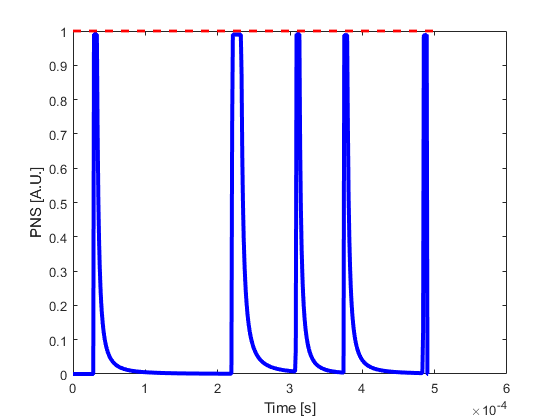

if isfield(params,'dt_out')
    params.dt = params.dt_out;
end

t = (0:params.dt:(length(G)-1)*params.dt)./100;
y = abs(get_stim(G, params.dt)');
figure; plot(t,y,'b','Linewidth',3);
    xlabel('Time [s]'); ylabel('PNS [A.U.]');
    hline = refline([0 1.0]); hline.Color = 'r'; hline.LineStyle = '--'; hline.LineWidth = 2;